problem1

clc;
clf;
clear;
% 부분 분수 형태의 계수 정의
R = [-9, 8]; 
p = [0.5, 1]; 
C = [2]; 
%residuez를 사용하여 arrange
[b, a] = residuez(R, p, C); %분자계수 b, 분모계수 a

%Zero, pole 계산
num = [1 2 1];
den = [1 -1.5 0.5];
zeros = roots(num)

zeros =     -1
    -1


poles = roots(den)

poles =     1.0000
    0.5000


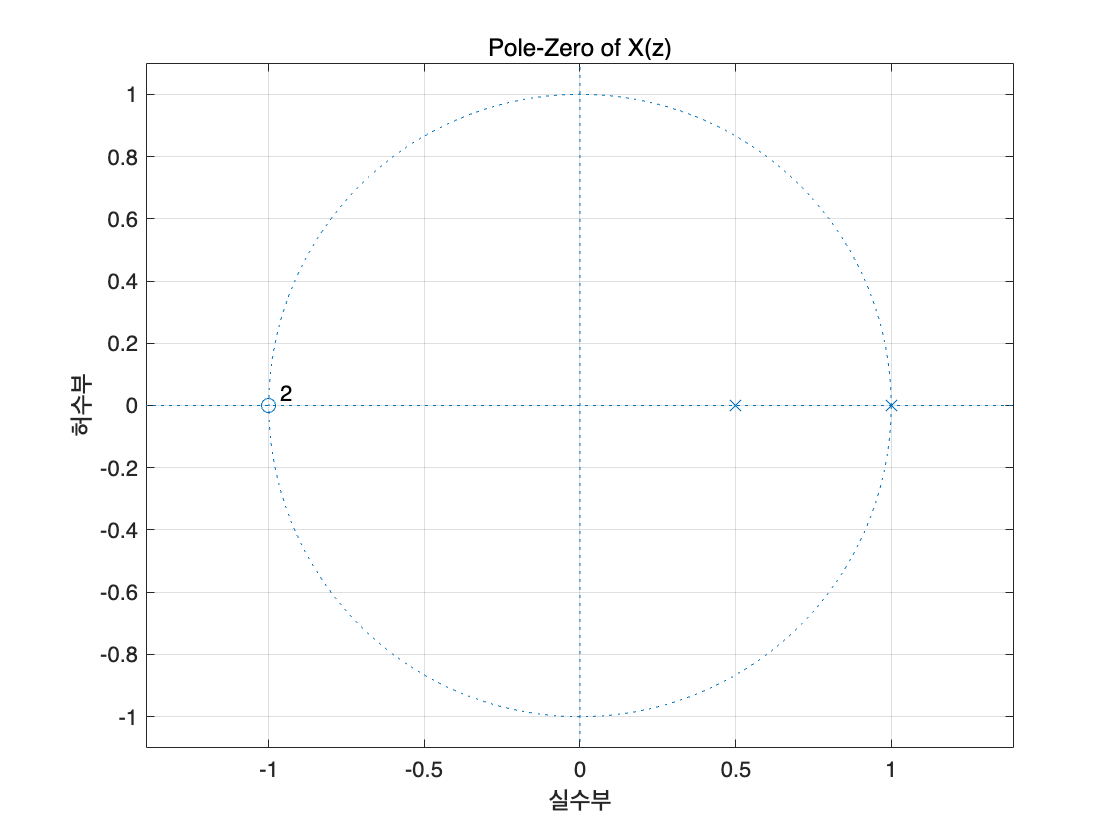


% Pole-Zero 그리기
figure; 
zplane(num, den);
title('Pole-Zero of X(z)');
grid on;

problem 2

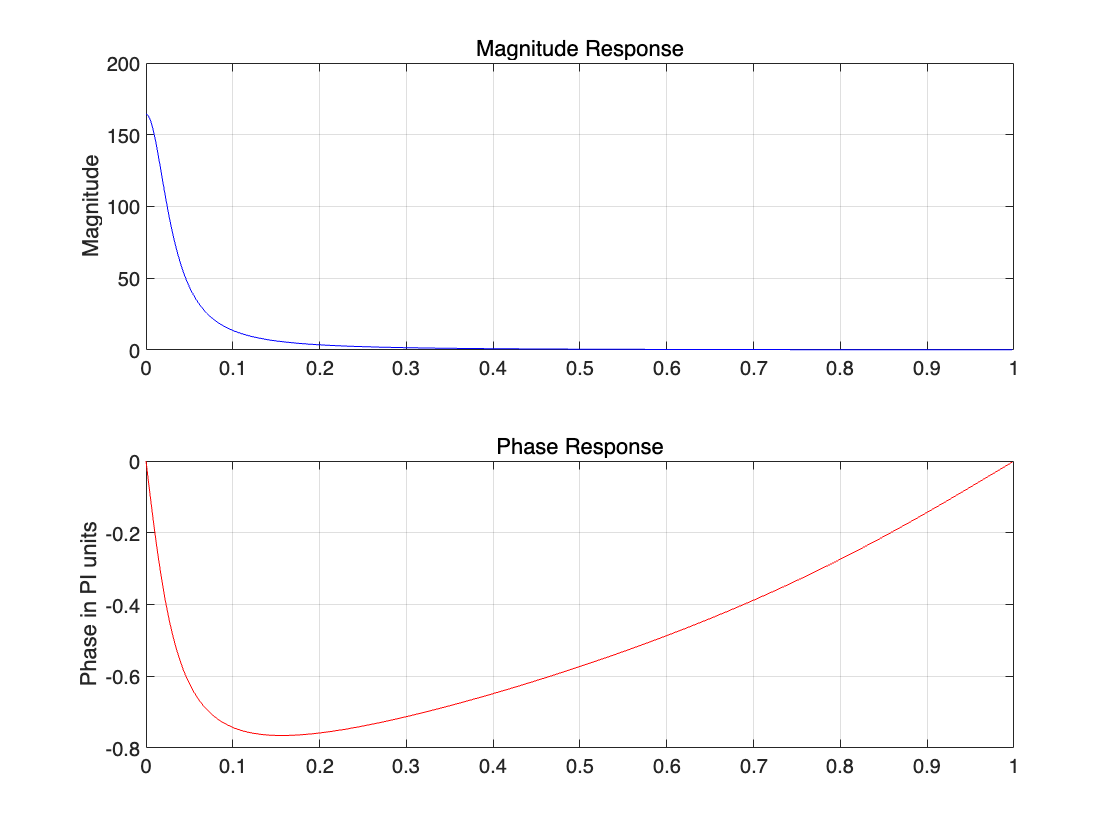


num = [1, 1/3]; %분자 계수
den = [1, -1.85*cos(pi/18), 0.83]; %분모 계수
%주파수 응답 계산
N = 512; %샘플 수
[H, w] = freqz(num, den, N, 'half'); 
magH = abs(H); %abs함수 이용
angH = angle(H)/pi;

%시각화
subplot(2,1,1);
plot(w/pi, magH, 'b');
ylabel('Magnitude');
title('Magnitude Response');
grid on;
subplot(2,1,2);
plot(w/pi, angH, 'r');
ylabel('Phase in PI units');
title('Phase Response');
grid on;

problem 3

num = [1, 3]; %분자 계수
den = [1, -1.5, 1, -1.5]; %분모 계수
%pole zero 계산
z = roots(num)

z = -3

p = roots(den)

p =    1.5000 + 0.0000i
  -0.0000 + 1.0000i
  -0.0000 - 1.0000i


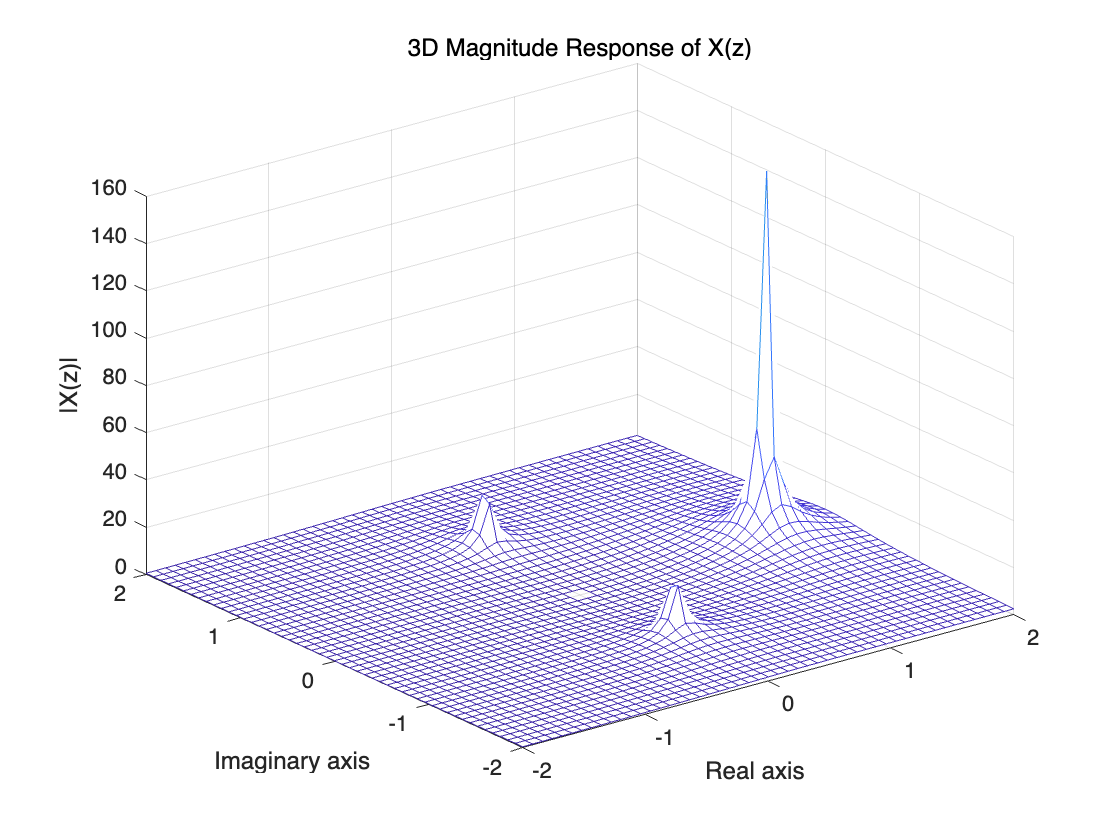


x = linspace(-2, 2, 51); %실수축
y = linspace(-2, 2, 51); %허수축
[X, Y] = meshgrid(x, y);
Z = X +1j*Y; 
%다항식 계산
X_num = 1 + 3 ./ Z;
X_den = 1 - 1.5 ./ Z + 1 ./ Z.^2 - 1.5 ./ Z.^3;
Xz = X_num ./ X_den; % 주파수 Response
magX = abs(Xz);

%시각화
figure;
mesh(X, Y, magX);
xlabel('Real axis');
ylabel('Imaginary axis');
zlabel('|X(z)|');
title('3D Magnitude Response of X(z)');
grid on;